clc
clear all
close all


# ELABORATO SERVOSYSTEMS & ROBOTICS

Link's dimentions expressed in meters:

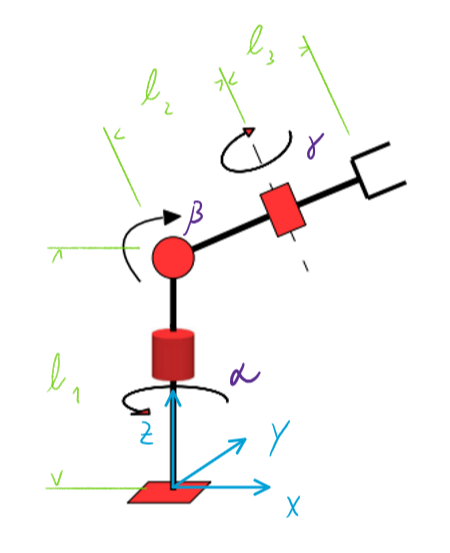

- Length of **Link 1**:

l1 = 1.2;

Link1 has a **Revolute Joint **that can freely rotate around the $z$ axis. $\alpha =\left\lbrack 0;\;2\pi \right\rbrack \ldotp$

- Length of **Link 2**:

l2 = 0.7;

Link2 has a **Revolute Joint **that can freely rotate in planes $y\;z$. $\beta =\left\lbrack 0;\;2\pi \right\rbrack$*. *

- Length of **Link 3**:

l3 = 0.4;

Link3 has a **Revolute Joint **that can freely rotate based on second link. $\gamma =\left\lbrack 0;\;2\pi \right\rbrack$.

        ** 2.  KINEMATICS & DYNAMICS**:

- Kinematics data:

L = [l1; l2; l3];    % matrice link [m]

- Direct kinematic configuration:

Qi = [0, 0, 0]'; % posizione iniziale
Qf = [0.2016, 0.1812, -2.4483]'; % posizione finale
dQ = Qf-Qi;

% limite accelerazione decelerazione velocità 3 giunti
A = [3,4,5];
D = [3,4,5];
V = [2,3,4];

for i = 1:3 % calcolo del minimo tempo di attuazione 
    [T(i),lambda1(i),lambda3(i)] = min_actuation_time_AAA(A(i),D(i),V(i),abs(dQ(i)));
end

[T,I] = max(T);
lambda1 = lambda1(I); % coeff tre tratti acc.
lambda3 = lambda3(I); % coeff tre tratti dec.

n = 500;
dT = T/n;

- Direct kinematic angular Speed Matrixes:

Lry= [0, 0, 1, 0; % attorno a y
      0, 0, 0, 0;
     -1, 0, 0, 0;
      0, 0, 0, 0];

Lrz=[0,-1, 0, 0; % attorno a z
     1, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 0, 0];

***DYNAMICS DATA***

- External forces (N):

Fx = 0; % forze agenti sul end effector
Fy = 0;
Fz = 0;

F_ext = [0,  0,  0,  Fx;
         0,  0,  0,  Fy;
         0,  0,  0,  Fz;
        -Fx,-Fy,-Fz, 0];

Hg = zeros(4);  % matrice di gravità 4x4
Hg(3,4) = -9.81; % asse z verso l'alto quindi gravità negativa

- Centri di gravità (dm):

g1 = 0.6; % lungo lasse baricentrale
g2 = 0.35;
g3 = 0.2;

G = [g1 g2 g3 1];

- Masse (kg) e inerzie:

% pesi presi da simulazione Solidworks di un robot in alluminio [kg]

m1 = 101.75;
m2 = 33.34;
m3 = 8.48;


% matrici inerzia prese da simulazione Solidworks di un robot in alluminio [kg*m] rispetto a sistema di rif baricentrale

Jx = [12.46 0.09 0.01];
Jy = [12.46 1.4 0.12];
Jz = [0.51 1.4 0.12];

Jxy = 0; Jxz = 0; Jyz = 0;

- Martrici Momenti di inerzia:

J1 = [Jx(1) Jxy Jxz;
      Jxy Jy(1) Jyz;
      Jxz Jyz Jz(1)];

J2 = [Jx(2) Jxy Jxz;
      Jxy Jy(2) Jyz;
      Jxz Jyz Jz(2)];

J3 = [Jx(3) Jxy Jxz;
      Jxy Jy(3) Jyz;
      Jxz Jyz Jz(3)];
  

- Shift Matrixes:

M1_1 = [1, 0, 0, 0; % asse baricentrale lungo z quindi shift in z
        0, 1, 0, 0; 
        0, 0, 1, -(l1-g1);
        0, 0, 0, 1]; 

M2_2 = [1, 0, 0, -(l2-g2); % asse baricentrale lungo x quindi shift in x
        0, 1, 0, 0;
        0, 0, 1, 0;
        0, 0, 0, 1];

M3_3 = [1, 0, 0, -(l3-g3); % asse baricentrale lungo x quindi shift in x
        0, 1, 0, 0;
        0, 0, 1, 0;
        0, 0, 0, 1];

- Pseudo insertia matrixes:

J1_1 = pseudoInertia(J1,m1); 
J11 = M1_1*J1_1*M1_1'; % traslazione pseudo inertia matrix sul sistema di riferimento a estremità link

J2_2 = pseudoInertia(J2,m2);
J22 = M2_2*J2_2*M2_2'; % traslazione pseudo inertia matrix sul sistema di riferimento a estremità link

J3_3 = pseudoInertia(J3,m3);
J33 = M3_3*J3_3*M3_3'; % traslazione pseudo inertia matrix sul sistema di riferimento a estremità link

- Definizione vettori per dati in cartesiano:

S = [];
Sp = [];
Spp = [];

- Definizione vettori dinamica:

J11_0 = []; % pseudo inertia matrix link 1 vista dal sistema di riferimento 0 (base).
J22_0 = [];
J33_0 = [];

FF1 = []; % forza totale sul link 1 vista dal sistema di riferimento 0 (base).
FF2 = [];
FF3 = [];

F_ext_0 = []; % forza totale sul end effector vista dal sistema di riferimento 0 (base).

EK_tot = []; % energia cinetica totale sul link 1 vista dal sistema di riferimento 0 (base).
EP_tot = []; % energia potenziale totale sul link 1 vista dal sistema di riferimento 0 (base).

CC1 = []; % coppia totale sul link 1 vista dal sistema di riferimento 0 (base).
CC2 = [];
CC3 = [];

WW1 = []; % potenza totale sul link 1 vista dal sistema di riferimento 0 (base).
WW2 = [];
WW3 = [];
WW4 = [];
WW_tot = []; % potenza totale (somma potenze link) vista dal sistema di riferimento 0 (base).


- Definizione vettori per dati nello spazio dei giunti.

Q = []; 
Qp = [];
Qpp = [];

***DIRECT KINEMATICS:***

for i = 1:n   
    t=(i-1)*T/(n-1);      % time from 0 to T with step dT
    tt(i)=t;
    
    % applicazione tre tratti per gli angoli alpha beta e gamma nel tempo
    % computato sopra come minimo tempo di attuazione per effettuare lo
    % spostamento da Qi a Qf
    [a(i),ap(i),app(i)] = tretratti(t,T,Qi(1),dQ(1),lambda1,lambda3); 
    [b(i),bp(i),bpp(i)] = tretratti(t,T,Qi(2),dQ(2),lambda1,lambda3);
    [c(i),cp(i),cpp(i)] = tretratti(t,T,Qi(3),dQ(3),lambda1,lambda3);
    
    q = [a(i);b(i);c(i)]; % vettore con valori degli angoli all'istante i
    qp = [ap(i);bp(i);cp(i)]; % vettore con valori delle velocità angolari all'istante i
    qpp = [app(i);bpp(i);cpp(i)]; % vettore con valori delle accelerazioni angolari all'istante i
    
    Q = [Q q]; % vettore con valori degli angoli in tutti gli istanti
    Qp = [Qp qp]; % vettore con valori delle velocità angolari in tutti gli istanti
    Qpp = [Qpp qpp]; % vettore con valori delle accelerazioni angolari in tutti gli istanti
    
    % calcolo mediante matrici 4x4 della cinematica diretta
    [s,M01,M12,M23] = Rotation_Matrixes_AAA(q,L); 
    
    S = [S s];
    
    M02 = M01*M12;
    M03 = M02*M23;
    
    % In generale Wij_k/Hij_k significa velocità/accelerazione di (j) rispetto ad (i) vista dal 
    % sistema di riferimento (k)  

- Speed Evaluation:

    w01_0 = Lrz*qp(1);      % speed in 0-1 seen by the referece system 0
    w12_0 = M01*Lry*qp(2)*inv(M01);     % speed in 1-2 seen by the referece system 0
    w23_0 = M02*Lrz*qp(3)*inv(M02);     % speed in 2-3 seen by the referece system 0
    
    w02_0 = w01_0 + w12_0;      % speed in 0-2 seen by the referece system 0 (sum of speed 0-1 % 1-2)
    w03_0 = w02_0 + w23_0;      % speed in 0-3 (gripper total speed) seen by the referece system 0 (sum of speed 0-2 % 2-3)
    
    sp = w03_0*s;       % linear speed of gripper is angular velocity multiplied by s.
    Sp = [Sp sp];

- Acceleration Evaluation:

    h01_0 = (Lrz*qpp(1) + Lrz^2*qp(1)^2);       % acceleration in 0-1 seen by the referece system 0, tangenziale e centripeta
    h12_0 = M01*(Lry*qpp(2) + Lry^2*qp(2)^2)*inv(M01);      % acceleration in 1-2 seen by the referece system 0 tangenziale e centripeta
    h23_0 = M02*(Lrz*qpp(3) + Lrz^2*qp(3)^2)*inv(M02);      % acceleration in 2-3 seen by the referece system 0 tangenziale e centripeta
    
    h02_0 = h01_0 + h12_0 + 2*w01_0*w12_0;      % acc in 0-2 seen by the referece system 0 (sum of acc 0-1 % 1-2 and coriolis between them)
    h03_0 = h02_0 + h23_0 + 2*w02_0*w23_0;      % acc in 0-3 seen by the referece system 0 (sum of acc 0-2 % 2-3 and coriolis between them)
    
    spp = h03_0*s;      % linear accelerazione of gripper is angular acceleration multiplied by s.
    Spp = [Spp spp];

***DYNAMICS EVALUATION:***

    j11_0 = M01*J11*M01'; % traslazione pseudo inertia matrix dal sistema di riferimento a estremità link alla base all'istante i
    j22_0 = M02*J22*M02';
    j33_0 = M03*J33*M03';
    
    J11_0 = [J11_0 j11_0]; % vettore delle pseudo inerzie in tutti gli istanti
    J22_0 = [J22_0 j22_0];
    J33_0 = [J33_0 j33_0];
    
    
    ff1i = -(h01_0*j11_0 - j11_0*h01_0'); % forza d'inerzia al link 1 all'istante i
    ff2i = -(h02_0*j22_0 - j22_0*h02_0');
    ff3i = -(h03_0*j33_0 - j33_0*h03_0');
    
    ff1g = Hg*j11_0 - j11_0*Hg'; % forza di gravità link1 all'istante i
    ff2g = Hg*j22_0 - j22_0*Hg';
    ff3g = Hg*j33_0 - j33_0*Hg';
    
    
    M0a = eye(4,4); % definizione matrice di traslazione forza esterna
    M0a(:,4) = M03(:,4); % matrice identità ma con l’ultima colonna pari a quella della matrice di collegamento primo e ultimo link
    fext_0 = M0a*F_ext*M0a'; % traslazione forza esterna al sistema di riferimento 0 (base) all'istante i.

    ff3 = ff3i+ff3g+fext_0; % forza totale agente sul link 3 (inerzia+gravità+esterna) istante i
    ff2 = ff2i+ff2g+ff3; % forza totale agente sul link 2 (inerzia+gravità+esterna = Forza Tot link3) istante i
    ff1 = ff1i+ff1g+ff2; % forza totale agente sul link 1 (inerzia+gravità+esterna = Forza Tot link2) istante i
    
    FF1 = [FF1 ff1]; % forza totale agente sul link 1 in tutti gli istanti
    FF2 = [FF2 ff2];
    FF3 = [FF3 ff3];
    
    F_ext_0 = [F_ext_0 fext_0]; % forza totale esterna agente sull'end effector in tutti gli istanti

- Kinematic Energy:

    ek1 = trace(1/2*w01_0*j11_0*w01_0'); % 1/2*J*w^2 prendendo la somma degli elementi sulla diagonale all'istante i
    ek2 = trace(1/2*w02_0*j22_0*w02_0');
    ek3 = trace(1/2*w03_0*j33_0*w03_0');
    
    ek_tot = ek1 + ek2 + ek3; % energia totale cinetica istante i
    
    EK_tot = [EK_tot ek_tot]; % vettore energie cinetiche totali in tutti gli istanti.

- Potential Energy:

    ep1 = -trace(Hg*j11_0); % (simile a m*g*h) prendendo la somma degli elementi sulla diagonale all'istante i
    ep2 = -trace(Hg*j22_0);
    ep3 = -trace(Hg*j33_0);

    ep_tot = ep1 + ep2 + ep3; % energia totale potenziale istante i
    
    EP_tot = [EP_tot ep_tot]; % vettore energie potenziali totali in tutti gli istanti.

- Torque of Forces:

    L12_0 = M01*Lry*inv(M01); % traslazione matrice rispetto al sistema di riferimento 0 (base)
    L23_0 = M02*Lrz*inv(M02); 
    
    cc1 = -PseDot(ff1,Lrz); % coppia giunto 1 calcolata con il pseudo prodotto scalare
    cc2 = -PseDot(ff2,L12_0); 
    cc3 = -PseDot(ff3,L23_0); 
    
    CC1 = [CC1 cc1]; % vettore coppia 1 in tutti gli istanti.
    CC2 = [CC2 cc2];
    CC3 = [CC3 cc3];

- Power of Forces:

    ww1 = -PseDot(ff1,w01_0); % potenza giunto 1 calcolata con il pseudo prodotto scalare
    ww2 = -PseDot(ff2,w12_0);
    ww3 = -PseDot(ff3,w23_0);
    ww4 = PseDot(fext_0,w03_0); % potenza richiesta in più dovuta alle forze esterne agenti sull'end effector calcolata con il pseudo prodotto scalare
    ww_tot = ww1+ww2+ww3+ww4; % potenza totale erogata dai giunti, istante i
    

- Calcoli verifica (debug):

    www1(i) = cc1*qp(1); % potenza giunto 1 calcolata come prodotto della coppia 1 e velocità angolare 1
    www2(i) = cc2*qp(2); 
    www3(i) = cc3*qp(3); 
    www_tot2(i) = www1(i)+www2(i)+www3(i)+ww4; % somma potenze
    
    WW1 = [WW1 ww1];
    WW2 = [WW2 ww2];
    WW3 = [WW3 ww3];
    WW4 = [WW4 ww4];
    WW_tot = [WW_tot ww_tot];


end

- Total Energy:

E_tot = EK_tot + EP_tot; 

- Total theoretical diff of power: for debug 

P_tot = theorethicalDiff(E_tot,dT); % derivata numerica dell'energia per istanti dT che fornisce la potenza totale

** 2.1 PLOT**:

- Plot configurations:

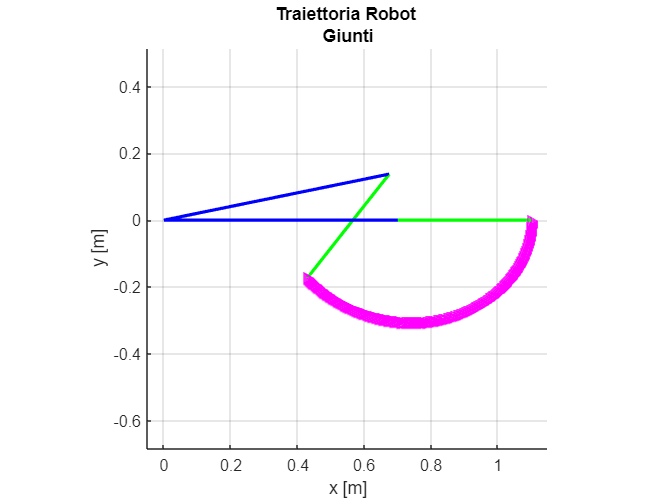

% Dati da cinematica diretta:
Plot_Trajectory_AAA(Qi,Qf,L,S(1,:),S(2,:),S(3,:),n,"Giunti");

- Plot graph of data x,y,z position speed and acceleration direct kinematics:

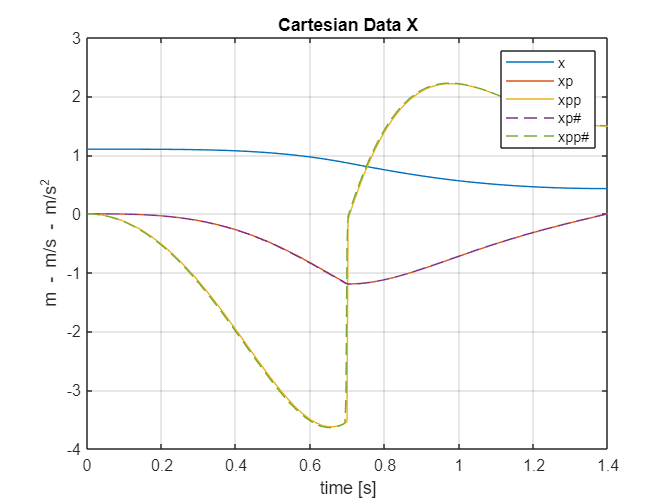

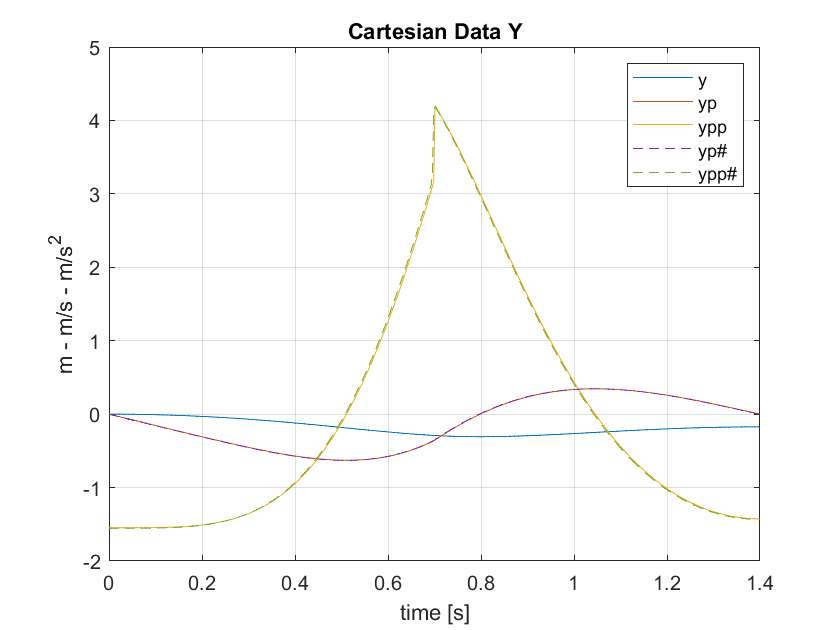

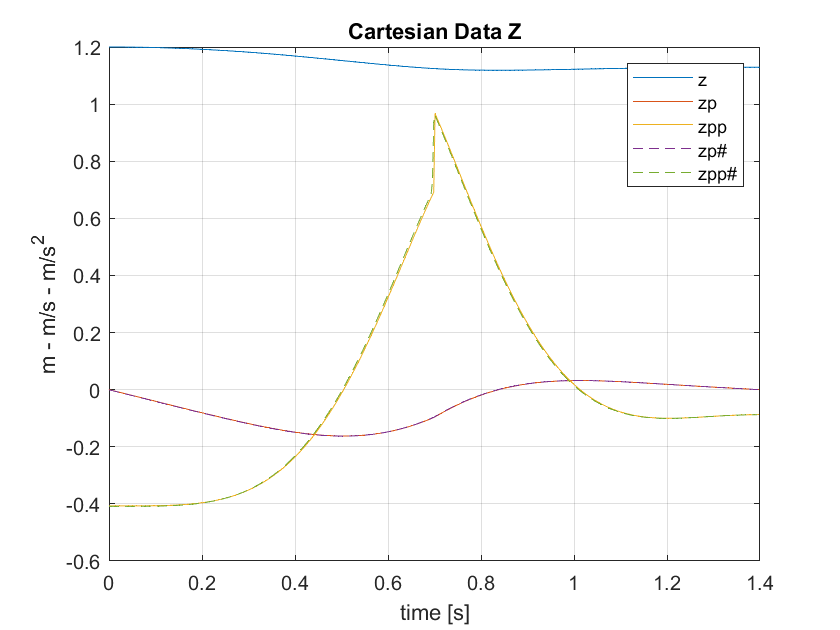

Plot_Graphs_Dir_Kinematics_AAA(S,Sp,Spp,tt,dT)

- Plot Coppie:

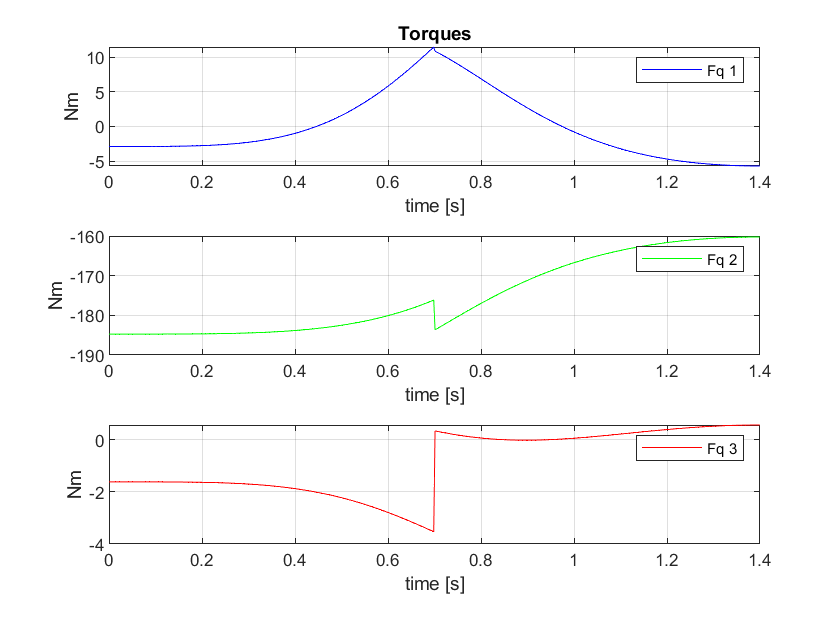

h = figure;
set(h,'name','torques')
subplot(3,1,1)
plot(tt,CC1,'b')
legend("Fq 1")
grid on
title("Torques")
ylabel('Nm')
xlabel('time [s]')

subplot(3,1,2)
plot(tt,CC2,'g')
legend("Fq 2")
ylabel('Nm')
xlabel('time [s]')
grid on

subplot(3,1,3)
plot(tt,CC3,'r')
legend("Fq 3")
ylabel('Nm')
xlabel('time [s]')
grid on

- Plot Energia:

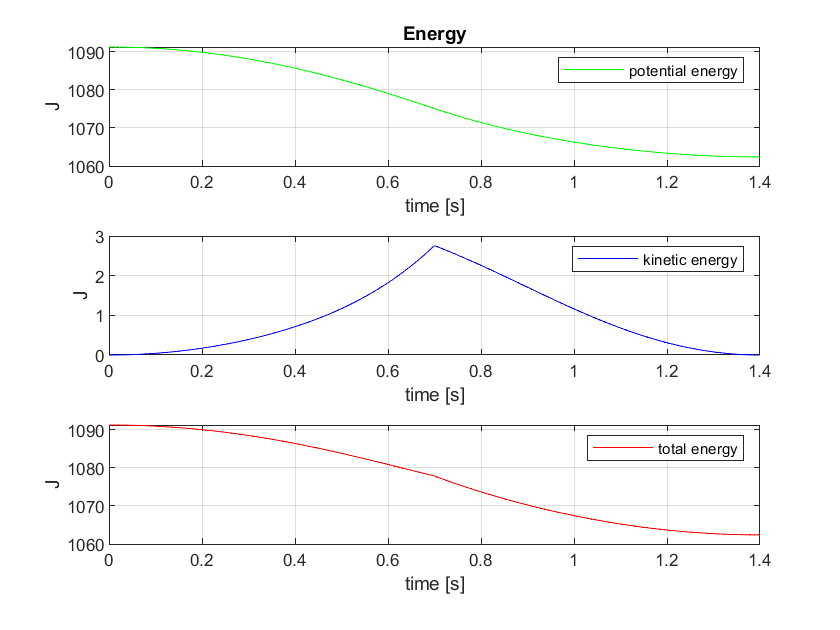

h = figure;
set(h,'name','energy') 

subplot(3,1,1)
plot(tt,EP_tot,'g')
legend("potential energy")
ylabel('J')
xlabel('time [s]')
grid on
title("Energy")

subplot(3,1,2)
plot(tt,EK_tot,'b')
legend("kinetic energy")
ylabel('J')
xlabel('time [s]')
grid on

subplot(3,1,3)
plot(tt,E_tot,'r')
legend("total energy")
ylabel('J')
xlabel('time [s]')
grid on

- Plot Potenze reali e teoriche:

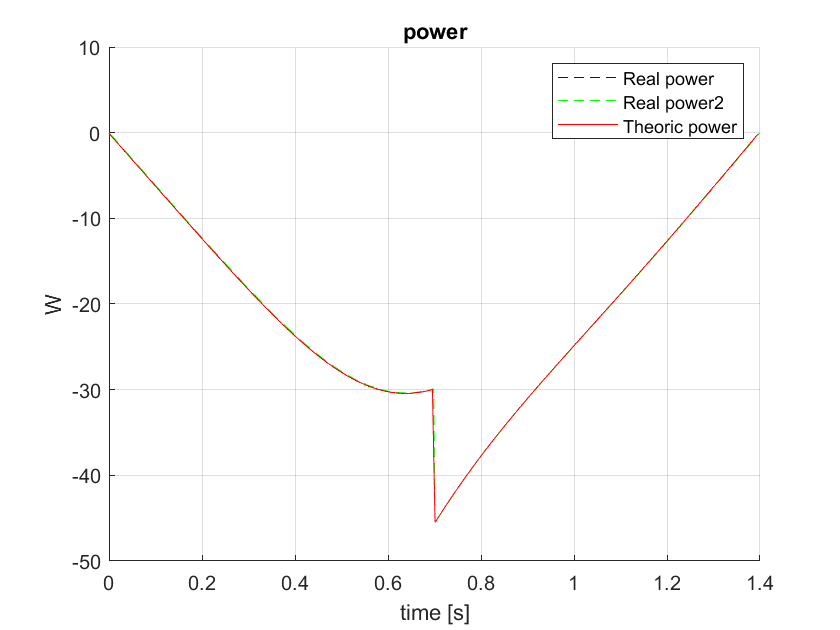

h = figure;
set(h,'name','power') 
hold on
grid on
plot(tt,WW_tot,'b--')
plot(tt,www_tot2,'g--')

plot(tt(1:length(P_tot)),P_tot,'r')
legend("Real power", "Real power2", "Theoric power")
ylabel('W')
xlabel('time [s]')
title("power")

- Plot tutte le potenze:

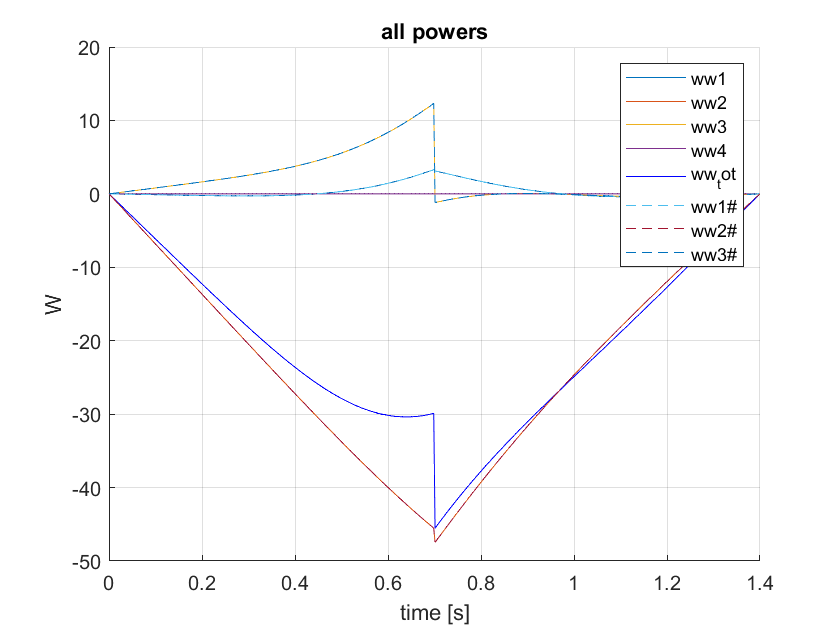

h = figure;
set(h,'name','all power') 

hold on
grid on

plot(tt,WW1)
plot(tt,WW2)
plot(tt,WW3)
plot(tt,WW4)
plot(tt,WW_tot,'b')

plot(tt,www1,'--')
plot(tt,www2,'--')
plot(tt,www3,'--')

legend("ww1","ww2","ww3","ww4","ww_tot","ww1#","ww2#","ww3#")
ylabel('W')
xlabel('time [s]')
title("all powers")


save dati1 Q Qp Qpp S Sp Spp CC1 CC2 CC3 EP_tot EK_tot E_tot WW_tot P_tot tt